**Part A and B**

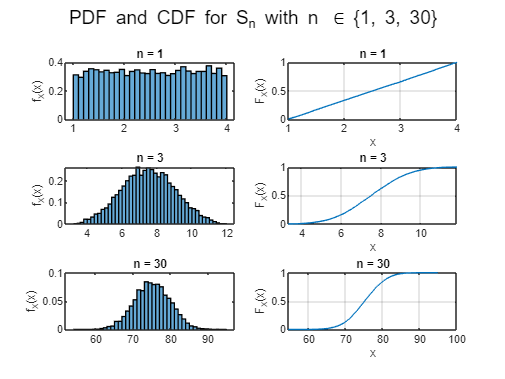

close all;clear all;

low_bound = 1;
top_bound = 4;

X = low_bound + (top_bound-low_bound)*rand(30,10^4);
Sn = cumsum(X); 

Gaussian_n_1 = makedist('Normal',  mu=1 * (5/2), sigma=sqrt(3/4));
Gaussian_n_3 = makedist('Normal',  mu=3 * (5/2), sigma=sqrt(3 * 3/4));
Gaussian_n_30 = makedist('Normal', mu=30 * (5/2), sigma=(sqrt(30 * 3/4)));

figure
s(1) = subplot(3,2,1) ;
    histogram(Sn(1,:),'Normalization','pdf',LineWidth=1);
    title(s(1),'n = 1')
    ylabel("f_X(x)")
s(2) = subplot(3,2,2) ;
    cdfplot(Sn(1,:))
    title(s(2),'n = 1')
    ylabel("F_X(x)")
s(3) = subplot(3,2,3);
    histogram(Sn(3,:),'Normalization','pdf',LineWidth=1)
    title(s(3),'n = 3')
    ylabel("f_X(x)")
s(4) = subplot(3,2,4);
    cdfplot(Sn(3,:))
    title(s(4),'n = 3')
    ylabel("F_X(x)")
s(5) = subplot(3,2,5);
    histogram(Sn(30,:),'Normalization','pdf',LineWidth=1)
    title(s(5),'n = 30')
    ylabel("f_X(x)")
s(6) = subplot(3,2,6);
    cdfplot(Sn(30,:))
    title(s(6),'n = 30')
    ylabel("F_X(x)")
sgtitle({'PDF and CDF for S_n with n \in \{1, 3, 30\}'})

**Part-C for superimpose**

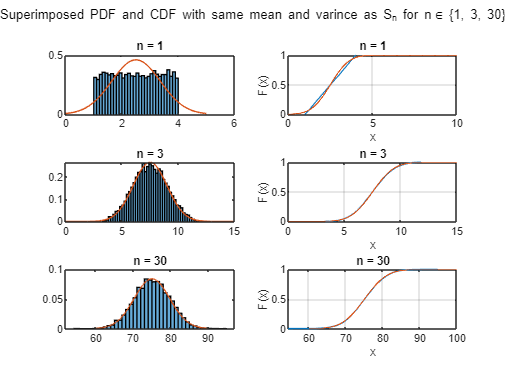

close all;
figure
s(1) = subplot(3,2,1) ;
    histogram(Sn(1,:),'Normalization','pdf',LineWidth=1);
    hold on;
    x = 0:0.01:5;
    plot(x,Gaussian_n_1.pdf(x));
    hold off;
    title(s(1),'n = 1')
s(2) = subplot(3,2,2) ;
    cdfplot(Sn(1,:))
    hold on;
    x = 0:0.01:10;
    plot(x,Gaussian_n_1.cdf(x),LineWidth=1);
    hold off;
    title(s(2),'n = 1')
s(3) = subplot(3,2,3);
    histogram(Sn(3,:),'Normalization','pdf',LineWidth=1)
    hold on;
    x = 0:0.01:15;
    plot(x,Gaussian_n_3.pdf(x));
    hold off;
    title(s(3),'n = 3')
s(4) = subplot(3,2,4);
    cdfplot(Sn(3,:))
    hold on;
    x = 0:0.01:15;
    plot(x,Gaussian_n_3.cdf(x),LineWidth=1);
    hold off;
    title(s(4),'n = 3')
s(5) = subplot(3,2,5);
    histogram(Sn(30,:),'Normalization','pdf',LineWidth=1)
    hold on;
    x = 60:0.01:90;
    plot(x,Gaussian_n_30.pdf(x));
    hold off;
    title(s(5),'n = 30')
s(6) = subplot(3,2,6);
    cdfplot(Sn(30,:))
    hold on;
    x = 60:0.01:100;
    plot(x,Gaussian_n_30.cdf(x),LineWidth=1);
    hold off;
    title(s(6),'n = 30')
sgtitle({'Superimposed PDF and CDF with same mean and varince as S_n for n\in \{1, 3, 30\}'},"Fontsize",10)

% When N is increase, pdf looks like gaussian and it verifies central
% limit theorem.
